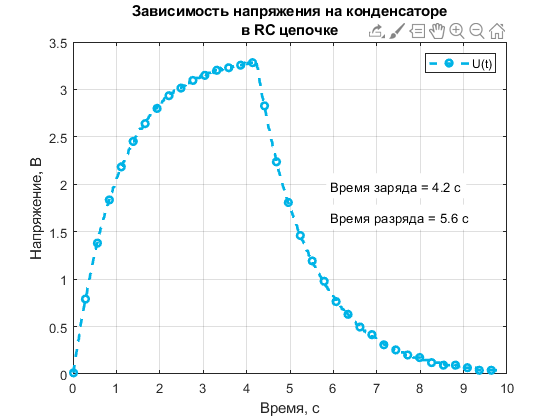

close all;
clear variables;

data = importdata("data.txt");
scale = importdata("settings.txt");

dV = scale(1);
dt = scale(2);

U = data * dV;
t = ((1:length(data)) * dt)';

tCharge = 4.2;
tDischarge = 5.6;

f1 = figure();
plot(t, U, 'g--o', 'MarkerIndices', 1:25:length(U), 'LineWidth', 2, 'MarkerSize', 5, 'Color', [0,0.7,0.9]);
grid on;
set(gcf, 'Visible', 'on');
title({'Зависимость напряжения на конденсаторе', 'в RC цепочке'});
xlabel("Время, с");
ylabel("Напряжение, В");
legend("U(t)", 'Location', 'northeast');
text(max(t) * 0.6, max(U) * 0.6, ['Время заряда = ', num2str(tCharge), ' с'], 'BackgroundColor', 'w');
text(max(t) * 0.6, max(U) * 0.5, ['Время разряда = ', num2str(tDischarge), ' с'], 'BackgroundColor', 'w');

saveas(f1, "cap.png");
"cap.svg");